# Characterization of DC motor with a gear ratio of 100:1

## 1. Create test data

maxPWM = 1.00;                         % Maximum duty cycle
incrPWM = 0.05;                        % PWM increment
PWMcmdRaw = (-maxPWM:incrPWM:maxPWM)'; % Column vector of duty cycles from -1 to 1

## 2. Create and initialize device objects

clear a carrier dcm enc                % Delete existing device objects

a = arduino;

enc = rotaryEncoder(a,'D0','D1',64);        % Connect the encoder of 'M1' at the encoder port 1 on the Nano Motor Carrier board

## 3. Measure raw motor speed for each PWM command

speedRaw = zeros(size(PWMcmdRaw));              % Preallocate vector for speed measurements

gearRatio = 10;                                % As per the motor spec sheet, gear ratio equals 100:1


for ii = 1:length(PWMcmdRaw)
    if PWMcmdRaw(ii)>0
        writePWMDutyCycle(a, 'D2', PWMcmdRaw(ii));
        writePWMDutyCycle(a, 'D3', 0);
        pause(1)                                    % Wait for steady state
        speedRaw(ii) = readSpeed(enc)/gearRatio;    % read motor speed in rpm of the output shaft

    else
        writePWMDutyCycle(a, 'D2', 0);
        writePWMDutyCycle(a, 'D3', -PWMcmdRaw(ii));
        pause(1)                                    % Wait for steady state
        speedRaw(ii) = readSpeed(enc)/gearRatio;    % read motor speed in rpm of the output shaft

end
end
writePWMDutyCycle(a, 'D2', 0);
writePWMDutyCycle(a, 'D3', 0);

## 4. Post-process and save data

idx = (diff(speedRaw) > 0);            % find indices where vector is increasing

speedMono4 = speedRaw(idx);             % Keep only increasing values of speed
PWMcmdMono4 = PWMcmdRaw(idx);           % Keep only corresponding PWM values

PWMcmdMono4(speedMono4 == 0) = 0;        % enforce zero power for zero speed

save motorResponse4 PWMcmdMono4 speedMono4 % save post-processed measurements

## 5. Graph raw and post-processed data

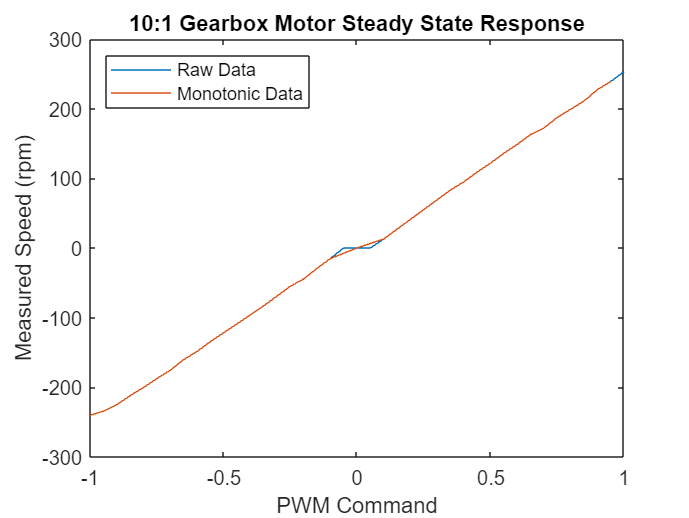

plot(PWMcmdRaw,speedRaw)    % raw speed measurements
hold on
plot(PWMcmdMono4,speedMono4)  % non-monotonic measurements filtered out

title('10:1 Gearbox Motor Steady State Response')
xlabel('PWM Command')
ylabel('Measured Speed (rpm)')
legend('Raw Data','Monotonic Data','Location','northwest')

## 6. Delete device objects

clear a carrier dcm enc

*Copyright 2018 - 2020 The MathWorks, Inc.*